clear; clc;
m = 1;
c = 0.2;
k = 10;
omega_n = sym(sqrt(k/m))

$$omega\_n = \sqrt{10}$$


xi = sym(c / (2* sqrt(m*k)))

$$xi = \frac{\sqrt{10}}{100}$$

omega_d = sqrt(1-xi^2)*omega_n

$$omega\_d = \frac{3\,\sqrt{111}}{10}$$

syms t
g = exp(-xi*omega_n*t)/(m*omega_d)*sin(omega_d*t)

$$g = \frac{10\,\sqrt{111}\,{\mathrm{e}}^{-\frac{t}{10}}\,\sin\left(\frac{3\,\sqrt{111}\,t}{10}\right)}{333}$$

f = piecewise(0 < t & t <= 2, 3*t, 2 < t & t <= 8, 8 - t)

$$f = \left\{ \begin{array}{cl} 3\,t & \text{ if }t\in \left(0,2\right]\\ 8-t & \text{ if }t\in \left(2,8\right] \end{array}\right.$$

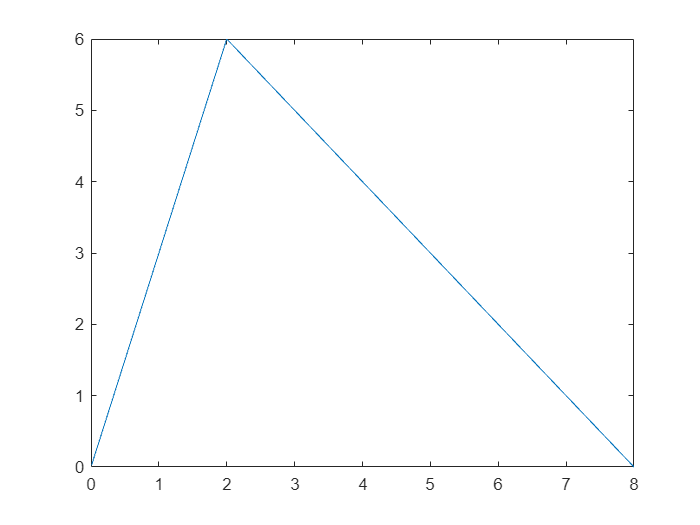

fplot(f, [0, 8])

syms tau
int_f = subs(f, t, tau) * subs(g, t, t - tau)

$$int\_f = \left\{ \begin{array}{cl} \frac{10\,\sqrt{111}\,\tau \,{\mathrm{e}}^{\frac{\tau }{10}-\frac{t}{10}}\,\sin\left(\frac{3\,\sqrt{111}\,\left(t-\tau \right)}{10}\right)}{111} & \text{ if }\tau \in \left(0,2\right]\\ -\frac{10\,\sqrt{111}\,{\mathrm{e}}^{\frac{\tau }{10}-\frac{t}{10}}\,\sin\left(\frac{3\,\sqrt{111}\,\left(t-\tau \right)}{10}\right)\,\left(\tau -8\right)}{333} & \text{ if }\tau \in \left(2,8\right] \end{array}\right.$$

x = int(int_f, tau, 0, t)

$$x = \begin{array}{l} \left\{ \begin{array}{cl} \frac{297}{500}-\frac{\sqrt{111}\,{\mathrm{e}}^{-\frac{1}{5}}\,\left(499\,\sin\left(\sigma_{1}\right)-3\,\sqrt{111}\,\cos\left(\sigma_{1}\right)\right)}{55500} & \text{ if }t=2\\ 0 & \text{ if }t\leq 0\\ \frac{\sigma_{2}\,\cos\left(\sigma_{5}\right)}{500}-\frac{301\,\sigma_{6}\,\cos\left(\sigma_{8}-\sigma_{1}\right)}{500}+\frac{199\,\sqrt{111}\,\sigma_{6}\,\sin\left(\sigma_{8}-\sigma_{1}\right)}{166500}-\frac{499\,\sqrt{111}\,\sigma_{2}\,\sin\left(\sigma_{5}\right)}{166500}-\sigma_{3}+\sigma_{4} & \text{ if }8\leq t\\ \frac{3\,t}{10}-\sigma_{3}-\frac{3}{500} & \text{ if }t\in \left(0,2\right]\\ \frac{199\,\sqrt{111}\,\sin\left(\sigma_{7}\right)\,\sigma_{6}}{166500}-\frac{301\,\sigma_{6}\,\cos\left(\sigma_{7}\right)}{500}-\frac{t}{10}-\sigma_{3}+\sigma_{4}+\frac{401}{500} & \text{ if }t\in \left(2,8\right] \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\sqrt{111}}{5}\\ \sigma_{2}={\mathrm{e}}^{\frac{4}{5}-\frac{t}{10}}\\ \sigma_{3}=\frac{\sqrt{111}\,{\mathrm{e}}^{-\frac{t}{10}}\,\left(499\,\sin\left(\sigma_{8}\right)-3\,\sqrt{111}\,\cos\left(\sigma_{8}\right)\right)}{55500}\\ \sigma_{4}=\frac{\sqrt{111}\,\sigma_{6}\,\left(599\,\sin\left(\sigma_{7}\right)+297\,\sqrt{111}\,\cos\left(\sigma_{7}\right)\right)}{55500}\\ \sigma_{5}=\sigma_{8}-\frac{12\,\sqrt{111}}{5}\\ \sigma_{6}={\mathrm{e}}^{\frac{1}{5}-\frac{t}{10}}\\ \sigma_{7}=\frac{3\,\sqrt{111}\,\left(t-2\right)}{10}\\ \sigma_{8}=\frac{3\,\sqrt{111}\,t}{10} \end{array}$$

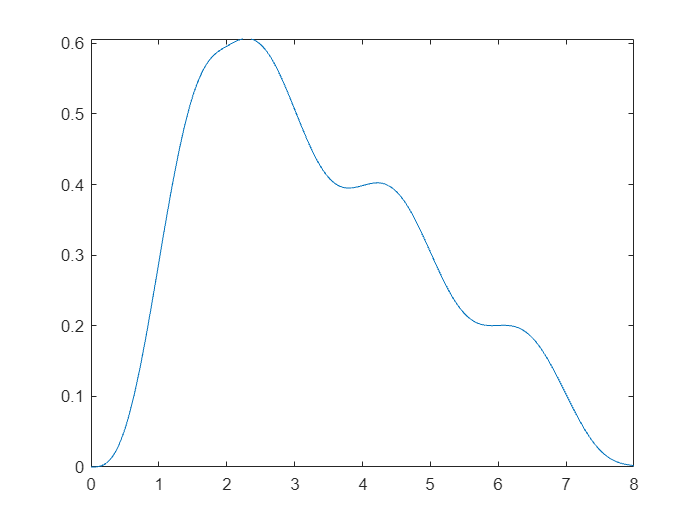

fplot(x, [0, 8])